addpath("/Users/penquin/Library/CloudStorage/OneDrive-KMITL/Project/function");
EmiPMs = ipOpa("/Users/penquin/Library/CloudStorage/OneDrive-KMITL/Project/DataBase/EmiPMs copy.xlsx", "Opacity", [3, Inf])

EmiPMs = 16×6 table
    Condition1    VarName7      B7      B7CeO2_300DOCPt_300PDPF      B10      B100 
    __________    ________    ______    _______________________    _______    _____

       1500          84          330              ""                2.3922    311.2
       1500         112        384.4              ""                2.6529    361.4
       1500         140        434.6              ""                5.5842      419
       1500         160          483              ""                 8.571    449.8
       2000          84          340              ""               0.73846    334.2
       2000         112       382.25              ""                1.0324    370.6
       2000         140          432              ""                2.0049    408.2
       2000        

EmiPMs = removevars(EmiPMs, ["B7CeO2_300DOCPt_300PDPF" "B10"]);
EmiPMs(13 : end, :) = [];
EmiPMs.Properties.VariableNames = ["RPM" "Torque" "B7" "B100"] 

EmiPMs = 12×4 table
    RPM     Torque      B7      B100 
    ____    ______    ______    _____

    1500      84         330    311.2
    1500     112       384.4    361.4
    1500     140       434.6      419
    1500     160         483    449.8
    2000      84         340    334.2
    2000     112      382.25    370.6
    2000     140         432    408.2
    2000     160       456.8    440.4
    2500      84         345    356.8
    2500     112       390.5    380.6
    2500     140       435.8    421.8
    2500     160         479    467.4


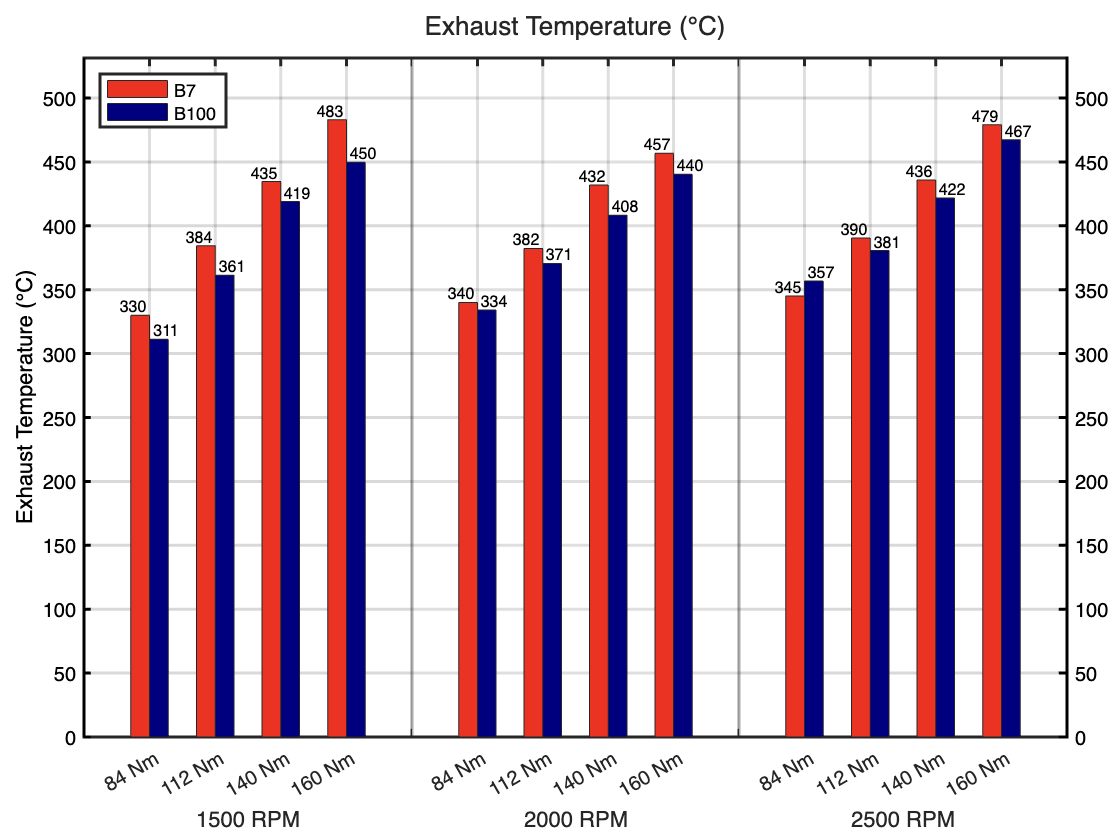

tile = ft_bar(EmiPMs, "Exhaust Temperature (°C)");